# Classifying Urban sounds using Machine Learning and Deep Learning

## 3 Model Training and Evaluation

Before training the model, I will convert the label in dataTrain_Validation  and dataTest from categorical array to string array. It is because categorical array does not accepted by code generation using MATLAB coder in deployment

dataTrain_Validation{:,15}=string(dataTrain_Validation{:,14});
dataTrain_Validation(:,14)=[];
dataTrain_Validation.Properties.VariableNames{14} = 'Label';

dataTest{:,15}=string(dataTest{:,14});
dataTest(:,14)=[];
dataTest.Properties.VariableNames{14} = 'Label';

## Train the model Using Classification Learner APP

Interactively train, validate, and tune classification models

Choose among various algorithms to train and validate classification models for binary or multiclass problems. After training multiple models, compare their validation errors side-by-side, and then choose the best model. To help you decide which algorithm to use, see [Train Classification Models in Classification Learner App](https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html).

classificationLearner

Taking into Consideration of Choosing the Right Model for you. 

[https://www.mathworks.com/help/stats/choose-a-classifier.html](https://www.mathworks.com/help/stats/choose-a-classifier.html)

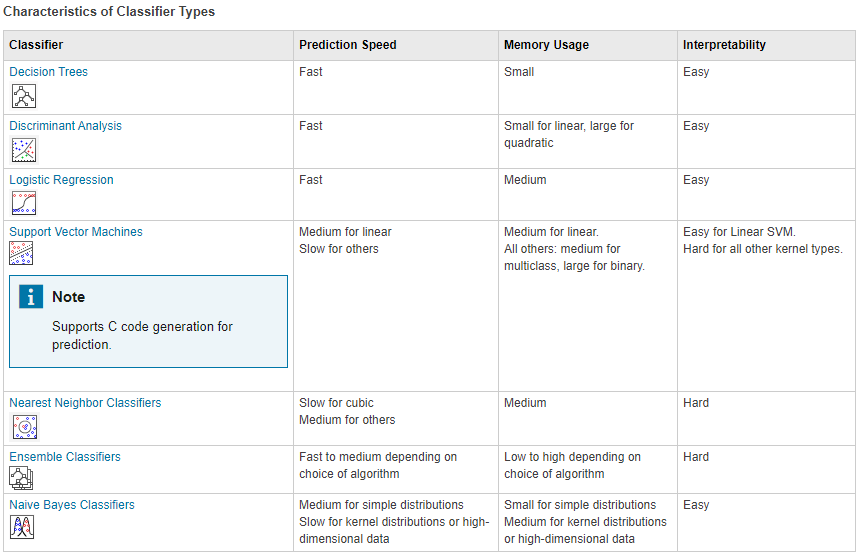

Training Model in Classification Learner App

1) Import Data with 10 folds

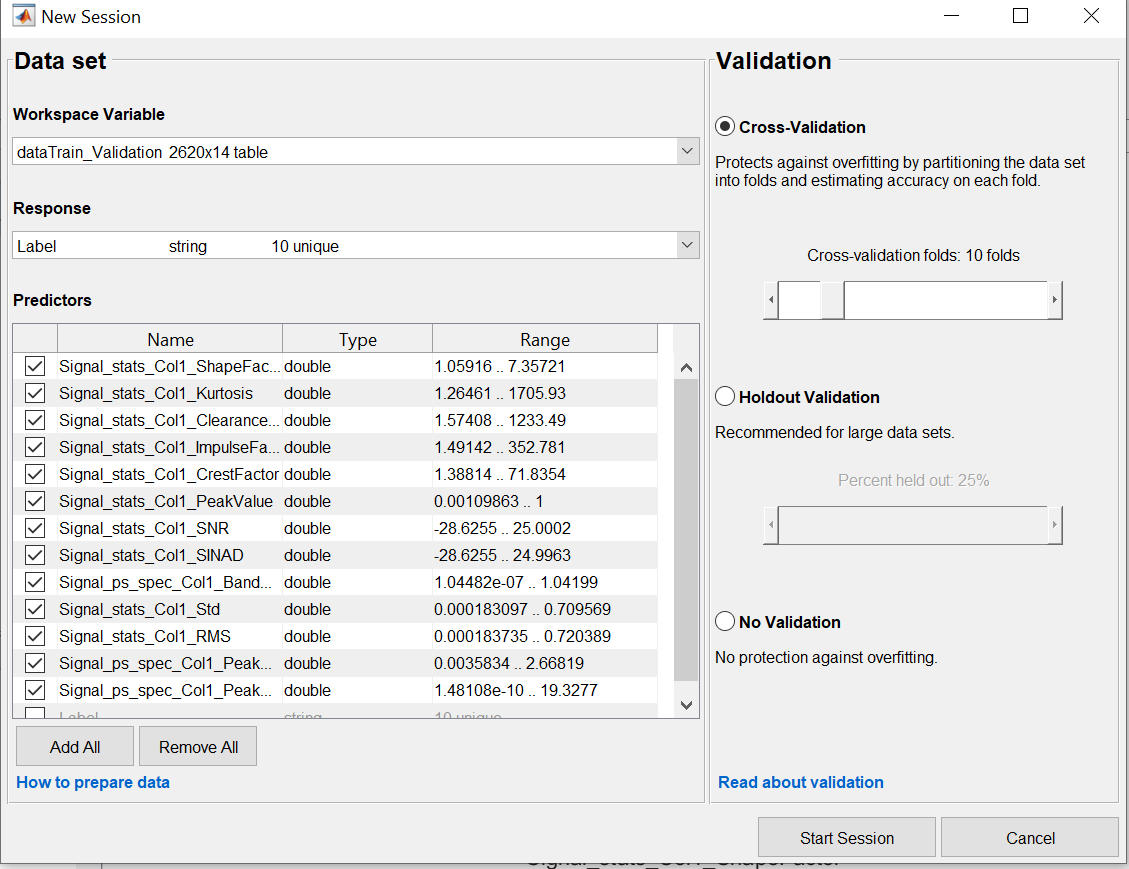

2) Train All Model

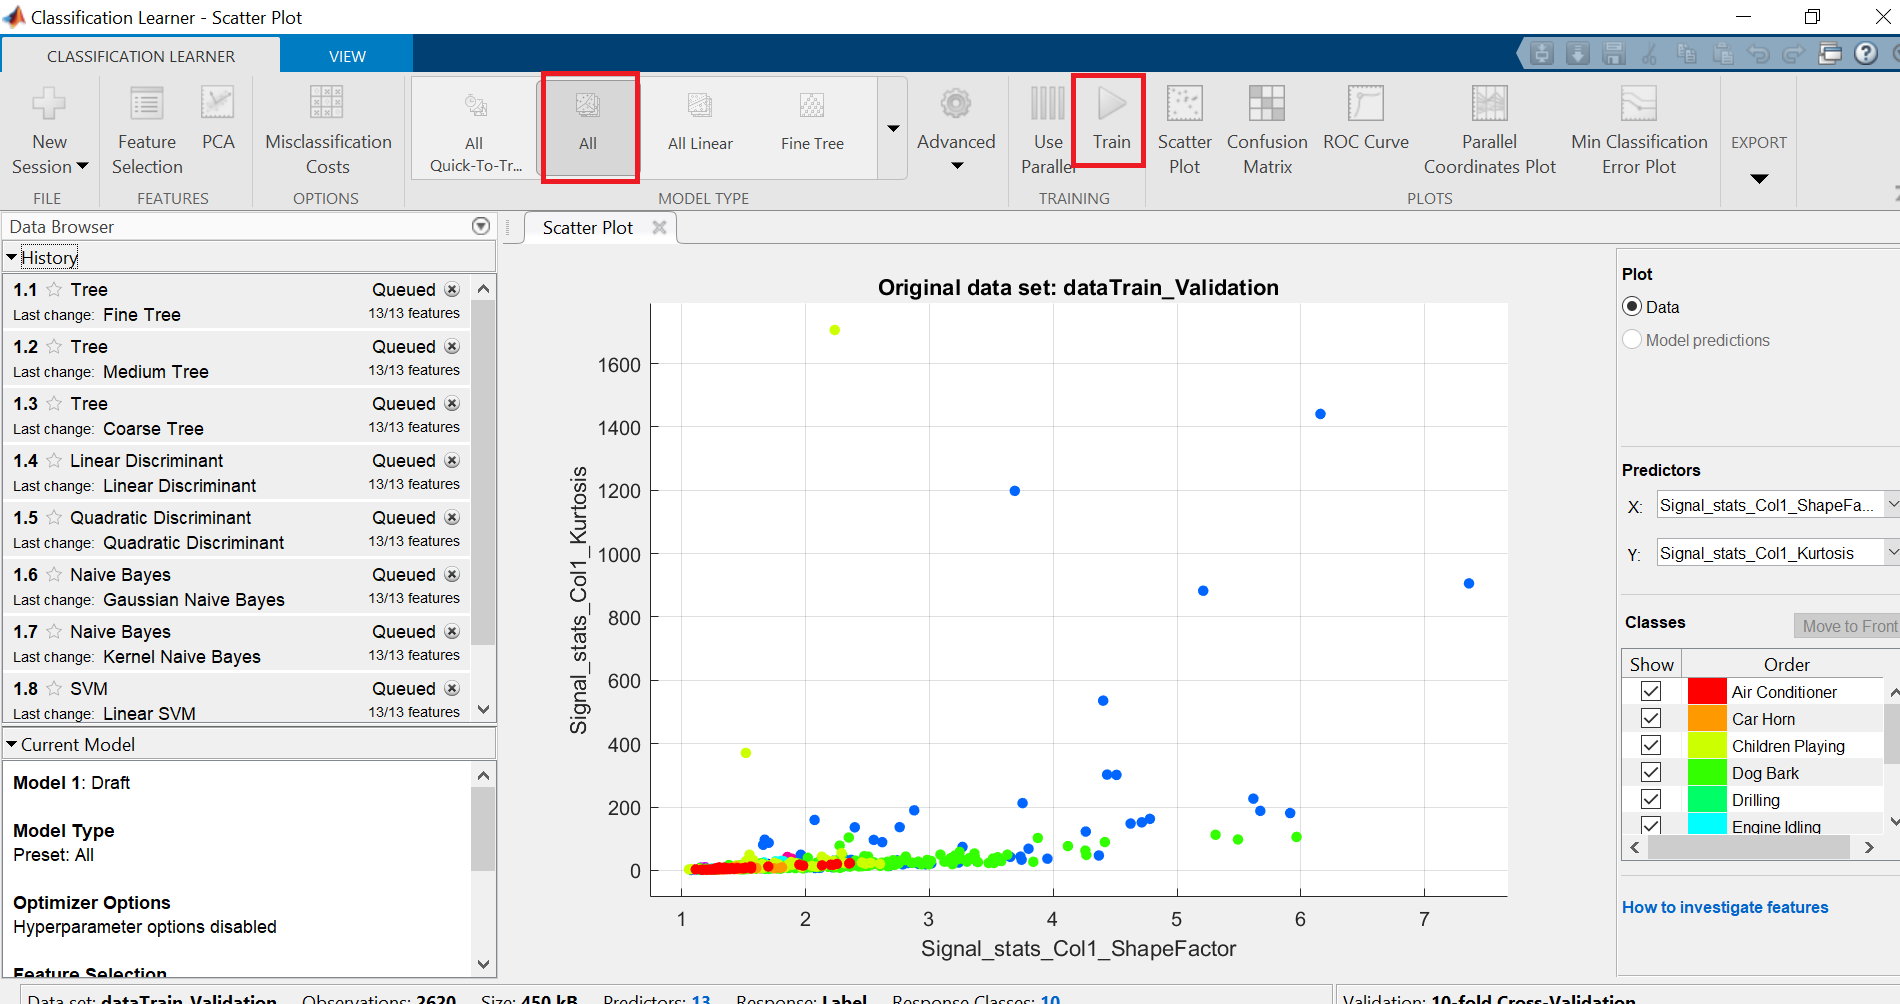

3) First run result, I found bag tree is the best model. 

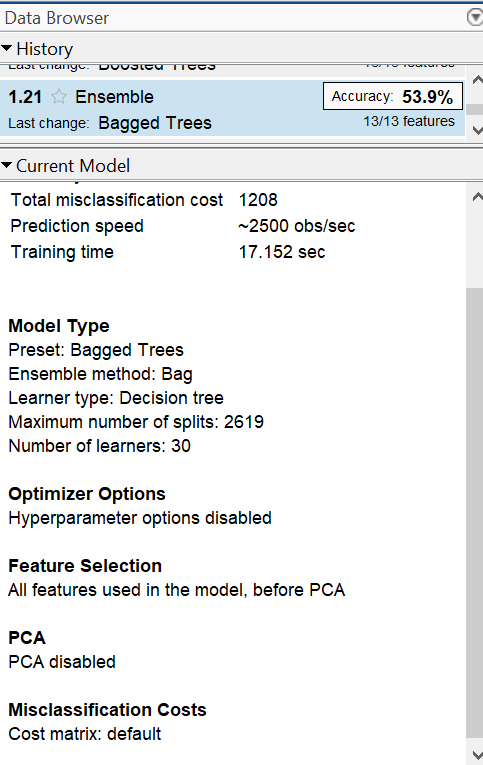

4) Now, we try to use bayesian optimization to optimize the model. (play around with the hyperparameters, see whether can you get higher accuracy model).

Please take note, try to matain the simplest nmodel with high accuracy, else big model might cause us problem in code generation.

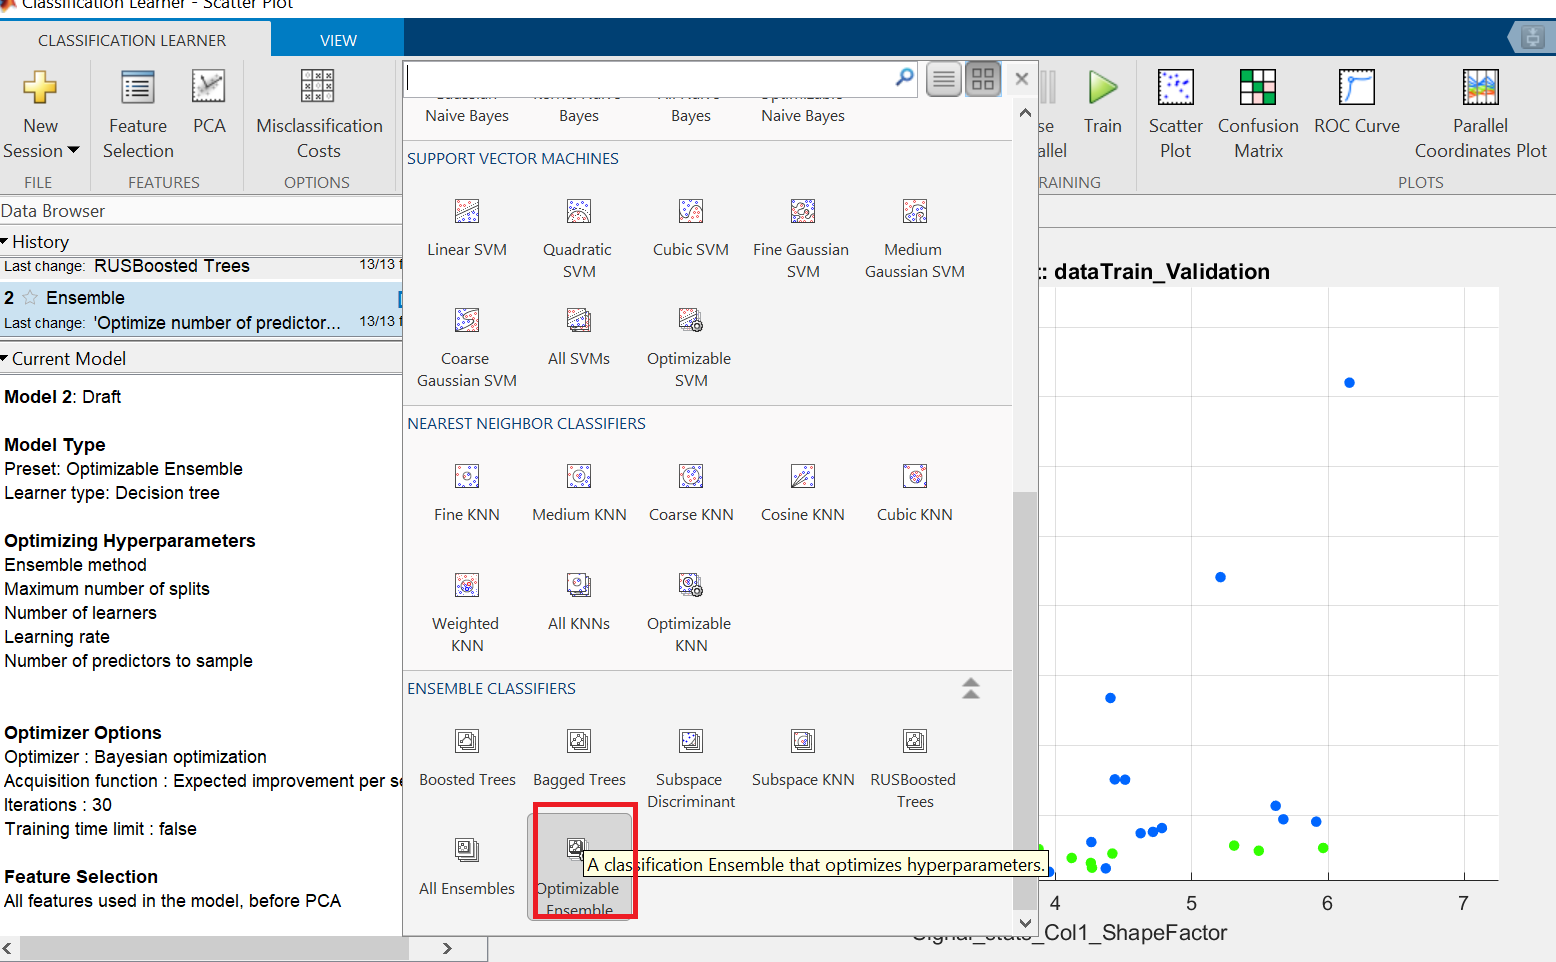

5) After Bayesian optimization, I still could not get model with better accuracy. Therefore, i try to impose higher misclassification costs on those wrong prediction more than 30.

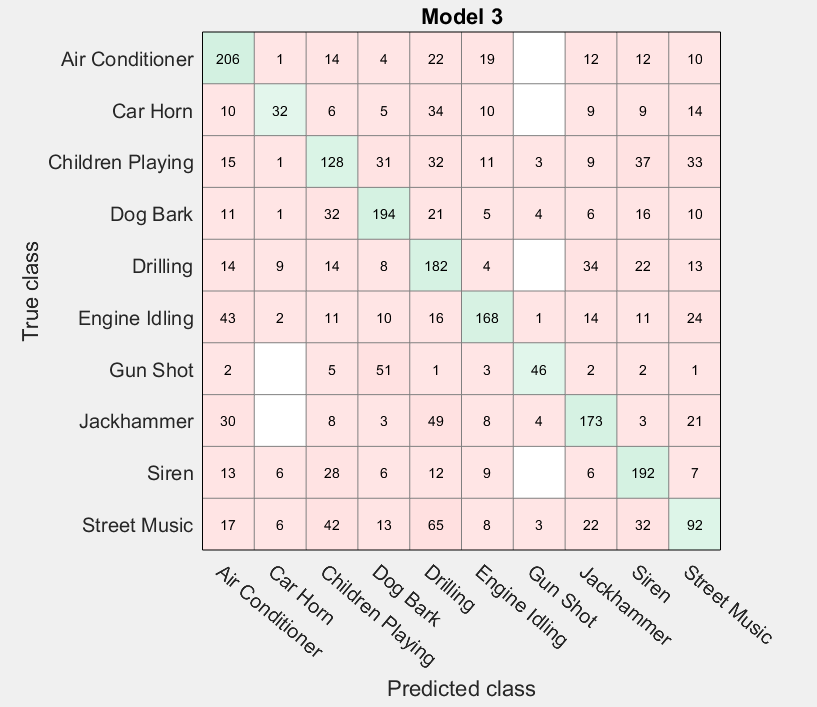

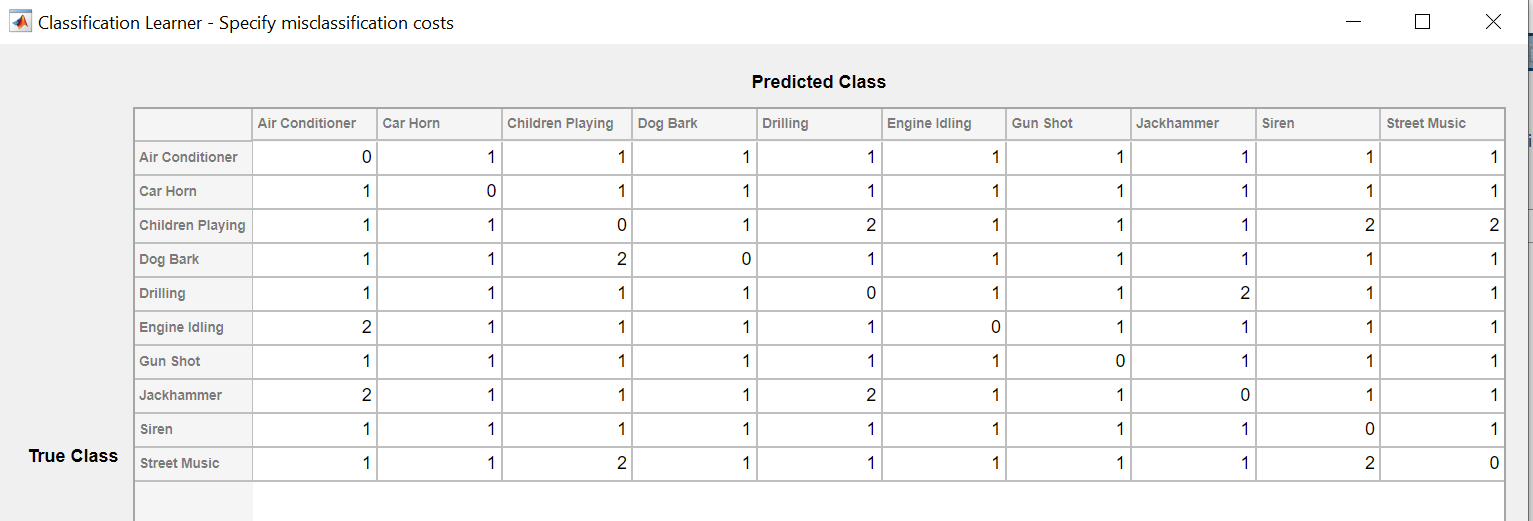

6) After playing around the parameters/hyperparameters, the model below is the best. It has reasonable training time and prediction speed.

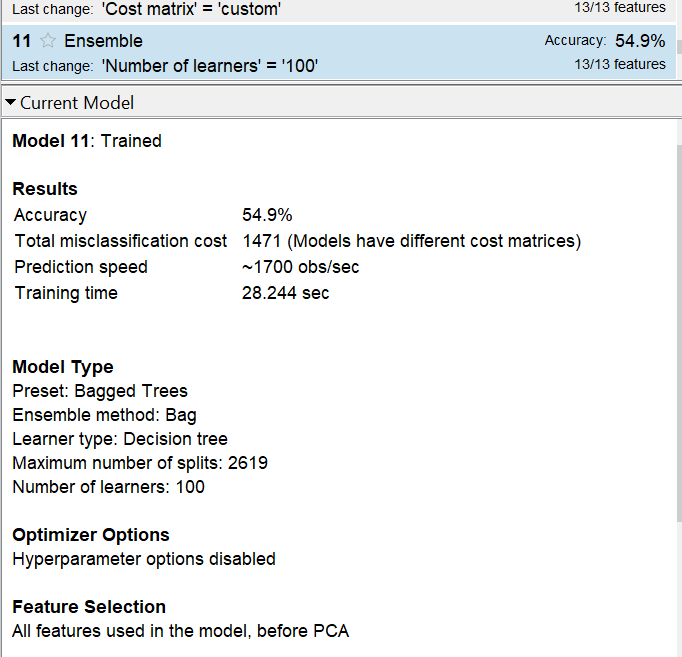

Since i could not able to increase the accuracy significantly, as expected from visualizing the data before machine learning, we can't get model with good accuracy.

7) Export the model

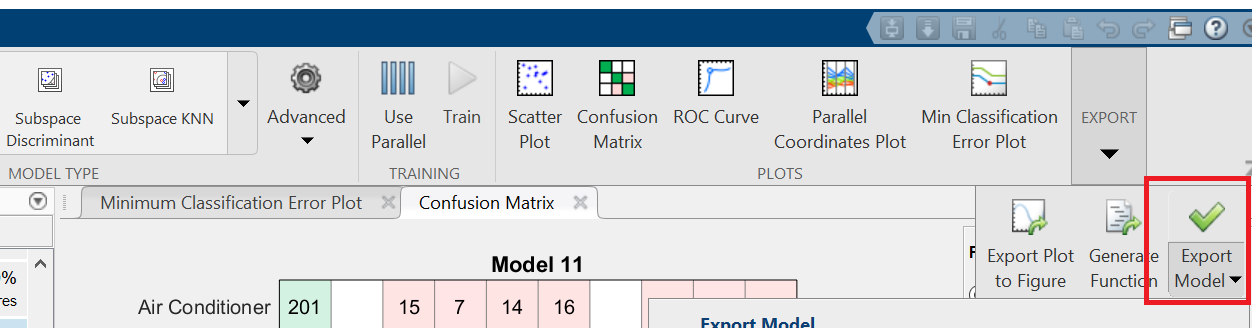

## Export Classification Model to Predict New Data

**Make Predictions for New Data**

After you export a model to the workspace from Classification Learner, or run the code generated from the app, you get a `trainedModel` structure that you can use to make predictions using new data. The structure contains a classification object and a function for prediction

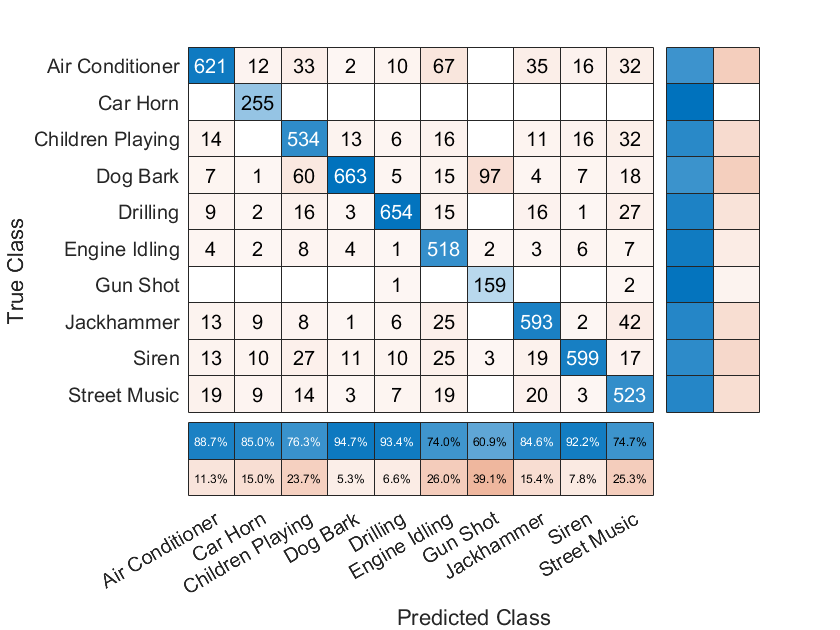

[predictionoutcome,scores]=trainedModel.predictFcn(dataTest);
fig = figure;
cm = confusionchart(string(predictionoutcome),dataTest.Label,'RowSummary','row-normalized','ColumnSummary','column-normalized');

accuracy=sum(string(predictionoutcome)==dataTest.Label)/length(dataTest.Label)

accuracy = 0.8375

Accuracy is 83.75%

Observation : 

We have noted down some important information before training, let review again :

***Observation from ML1***

1) With our eye, we can differenciate the sound using their shape of signal. Am I right? Now, we take note about it first.

- Shape factor is the most important factor in our ranking, therefore, we prove it right. However, with time domain and spectral features, we dont have much information about the shape, hence, we only able to hit the prediction up to 55%.

***Observation from ML2***

1) if we look at the shape of signal, we will notice some are looking similar to each other although we still can differentiate it through sound. Especially, gun shot is looking smilar to jackhammer. Drilling and Engine Idling are also looking similar.

- It is correct. In my intuitive, i try to impose higher penalty for the cost matrix to deal with this, however, I failed to increase the accuracy significantly.

2) if we are looking at the graph, many classes does not have significant distinction, we might dont have good accuracy result if we only use time-domain and spectral features to train machine learning model.

- Now it is time for us to think what other features we can included which the features will tell more information about the shape. MFCC or Wavelet transform?

**Generate MATLAB Code to Train the Model with New Data**

After you create classification models interactively in Classification Learner, you can generate MATLAB code for your best model. You can then use the code to train the model with new data.

saveLearnerForCoder(trainedModel.ClassificationEnsemble,'bagtree');

ans = 1×1 cell array
    {'Air Conditioner'}


function label = classifyurbansound(X) %#codegen
Mdl = loadLearnerForCoder('bagtree');
label = predict(Mdl,X);
end